# Seminar 9 - Unscendet Kalman filter (UKF)

**Authors:**  Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

In last seminar we explored the EKF and IEKF filters. Another way how to handle nonlinearity is unscendet transformation and on it based unscendet kalman filter (UKF). EKF and KF is based on linearizing the nonlinear dynamics. On the other hand the UKF keeps the nonlinear system as is and captures also the second moment (and possibly also higher) of the random varible. This is achieved via storing the so called sigma points. These sigma points are then mapped with the nonlinear dynamics onto next state and after that the first and second moment is recomputed from these.

## Battery state of charge estimation - UKF and IEKF (EKF)

Let's consider the same model as in previous seminar. A Li-ion battery that is described by the following equations


$$\begin{array}{l}
\frac{\mathrm{d}\;i}{\mathrm{d}\;t}=10\left(u-i\right)\;\;,\\
\dot{\textrm{SOC}} =\frac{1}{Q}i
\end{array}$$


where $i$ is current of the battery, $Q$ is capacity of the battery, SOC is state of charge and $u$ is commanded current. Parameters of the system will be stated directly in the pre-prepared script. Input to the system is also prepared for you. Let's define the state of the battery as $x=\left\lbrack \begin{array}{c}
i\\
\textrm{SOC}
\end{array}\right\rbrack$. Assume that we are able to measure open circuit voltage of the battery. So the measurement eaution is:

$y=\textrm{OCV}\left(\textrm{SOC}\right)+e$,

where $\textrm{OCV}\left(\textrm{SOC}\right)$ is function fitted on the data provided by the battery manufacturer and $e$ is measurement noise. Both the measurement and process noise covariances (Q and R) are valued in the pre-prepared script.

Your task will be:

- Implement the unscendet kalman filter UKF

- Plot the sigma points of the state and following state together with the 25%, 50% and 95% confidence bounds in the phase plane for the first estimate (you can try also other ones) before and after the time step. This part is already prepared for you.

- Implement the iterated extended kalman filter (IEKF)

- Change the implementation of IEKF to EKF and compare differences

- Compare the estimates (plot the estimates and print the resulting RMSE) for IEKF and UKF - already done

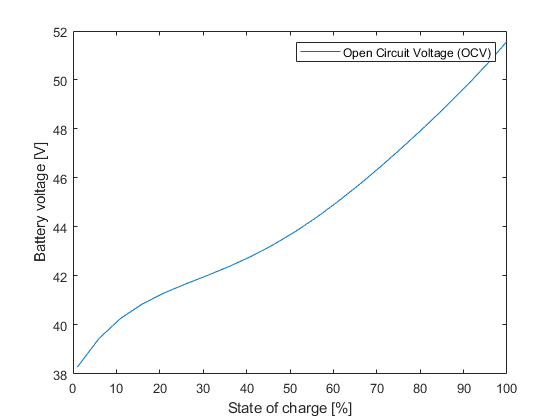

N =1000;            % num of steps
Ts = 0.01;          % time step
C_AH = 2;          % Ah
Qr = C_AH*36;       % Convert to charging constant
taui = 10;        % time constant for current tracking

Q  = 0.01*eye(2);                   % process noise covariance
R  = 0.001;                                               % measurement noise covariance
QL = chol(Q,'lower');

% Nonlinear system functions
f = @(x, u, v)([(taui*(u - x(1))*Ts + x(1)); ...
    (1/Qr*x(1))*Ts + x(2)]+ QL*v);
h = @(x,e)(38 + 0.295*x(2) - 0.01*x(2)^2 + 1.9694e-04*x(2)^3 - 1.652e-06*x(2)^4 + 5.234e-09*x(2)^5 + sqrt(R)*e);

SOC = [1:5:100 100];
OCV = zeros(numel(SOC), 1);
for i = 1:numel(SOC)
    OCV(i) = h([0 SOC(i)], 0);
end
figure;
plot(SOC, OCV);
legend('Open Circuit Voltage (OCV)');
ylabel('Battery voltage [V]');
xlabel('State of charge [%]');

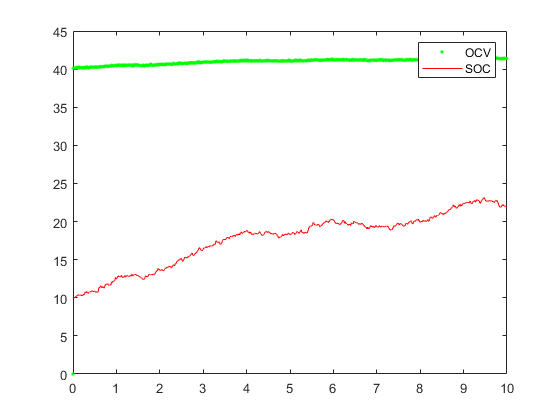

% Jacobians
fd = @(x)([(1 - Ts*taui) 0;Ts/Qr 1]);
hd = @(x)([0 (0.2945 - 2*0.0102*x(2) + 3*1.9694e-04*x(2)^2 - 4*1.6518e-06*x(2)^3 + 5*5.2344e-09*x(2)^4)]);

% Init
T = (0:N-1)*Ts;
X = zeros(2,N);
Y = zeros(1,N);
U = 80*abs(randn(1,N));

% Simulate
x0 = [1;10];
X(:,1) = x0;
for k= 2:N
    x = f(X(:,k-1), U(:,k-1),randn(2,1));    % state measurements with gwn
    y = h(x,randn);                 % output measurements with gwn
    X(:,k) = x;
    Y(:,k) = y;
end


% Plot simulation
figure;
plot(T,Y,'g.',T,X(2,:),'r-');
legend('OCV', 'SOC');


%% IEKF

x0 = [4;10];       % Slightly off
P0 = 30*eye(2);
eps = 1e-2;


% initialize
xhat_IEKF = x0;
xhat_ukf = x0;
P_IEKF = P0;
P_UKF = P0;
XXhat_IEKF = zeros(size(xhat_IEKF,1),length(Y));
XXhat_IEKF(:,1) = x0;
XXhat_UKF = zeros(size(xhat_IEKF,1),length(Y));
XXhat_UKF(:,1) = x0;

% UKF initialize
n = numel(x0);
w = zeros(2*n + 1, 1);
k = 3 - n;
w(1) =  k/(n + k);
w(2:end) = 1/(2*(n + k))*ones(numel(w(2:end)),1);


% Unit circle parametrization
Ncircle = 100; % number of elements in graph
theta = [0:1/Ncircle:2*pi+1/Ncircle];

% Quantiles
quantiles = [0.25,0.5, 0.95];
quant_norm = (quantiles-min(quantiles)*0.6)/0.75; % normalization used only for plotting

cm = colormap('jet');

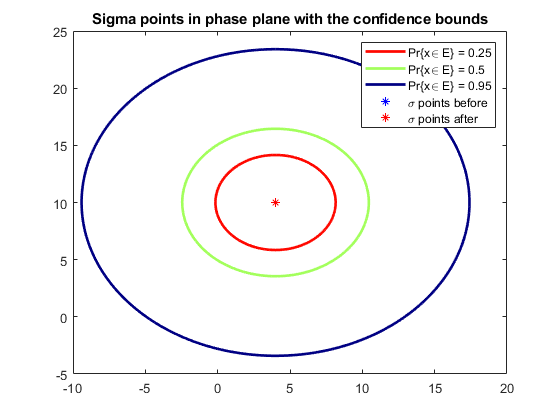

ncm = size(cm,1);


% x,y coordinates
unit_circle(1,:) = cos(theta); % x
unit_circle(2,:) = sin(theta); % y 

for k=2:length(Y)
     % Data step IEKF
     % IMPLEMENT
     
     % Data step UKF
     % IMPLEMENT
     
    
    % Time step UKF
    % IMPLEMENT the x sigma points computations before the plotting of the
    % phase planes
    x_sigma = x0;
    if k == 2
        % plot the first estimate
        [U_calc,D_calc,~] = svd(P_UKF);
        figure;
        for i = 1:numel(quantiles)
            q = quantiles(i);
            alpha = chi2inv(q,2);
            % plot calculated covariance and center
            sig_contour_calc = U_calc*sqrt(alpha*D_calc)*unit_circle;
            sig_contour_calc(1,:) = sig_contour_calc(1,:)+ xhat_ukf(1);
            sig_contour_calc(2,:) = sig_contour_calc(2,:)+ xhat_ukf(2);
            plot(sig_contour_calc(1,:),sig_contour_calc(2,:),...
                'LineWidth',2,'Color',cm(max(round((1-quant_norm(i))*ncm),1),:),...
                'DisplayName',['Pr\{x\in E\} = ',num2str(q)]);
            hold on;
        end
        plot(x_sigma(1, :), x_sigma(2,:), 'b*', 'DisplayName', '\sigma points before');
    end
    
    
    % IMPLEMENT the UKF Time step
    
    if k == 2
        % plot the first estimate after the time step
        [U_calc,D_calc,~] = svd(P_UKF);
        for i = 1:numel(quantiles)
            q = quantiles(i);
            alpha = chi2inv(q,2);
            % plot calculated covariance and center
            sig_contour_calc = U_calc*sqrt(alpha*D_calc)*unit_circle;
            sig_contour_calc(1,:) = sig_contour_calc(1,:)+ xhat_ukf(1);
            sig_contour_calc(2,:) = sig_contour_calc(2,:)+ xhat_ukf(2);
            plot(sig_contour_calc(1,:),sig_contour_calc(2,:),...
                'LineWidth',2,'Color',cm(max(round((1-quant_norm(i))*ncm),1),:),...
                'HandleVisibility','off');
            hold on;
        end
        plot(x_sigma(1, :), x_sigma(2,:), 'r*', 'DisplayName', '\sigma points after');
        legend();
        title('Sigma points in phase plane with the confidence bounds');
    end
    
    
    
        
    % Time step EKF
    % IMPLEMENT
    
    
    XXhat_IEKF(:,k) = xhat_IEKF;
    XXhat_UKF(:,k) = xhat_ukf;
end


rmse_ekf = sqrt(mean((X(2,:)-XXhat_IEKF(2,:)).^2))

rmse_ekf = 8.4523

rmse_ukf = sqrt(mean((X(2,:)-XXhat_UKF(2,:)).^2))

rmse_ukf = 8.4523

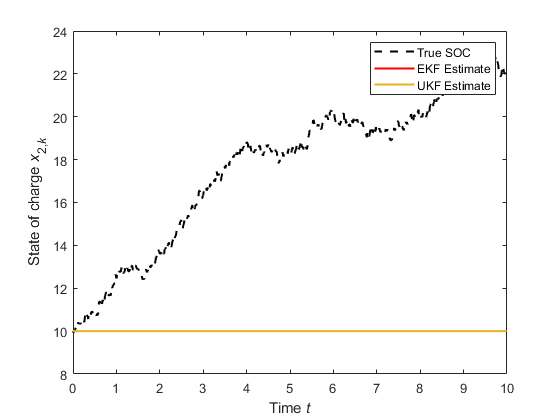


figure;
p=plot(T,X(2,:),'--k',T,XXhat_IEKF(2,:),'r', T,XXhat_UKF(2,:), 'Linewidth',1.5);
legend('True SOC','EKF Estimate', 'UKF Estimate');
xlabel('Time{\it t}');
 ylabel('State of charge {\it{x}}_{2,{\it{k}}}')

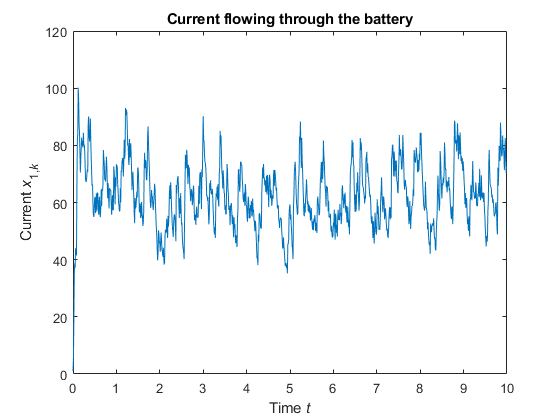

%  ylim([-60 100]);

figure;
plot(T, X(1,:));
title('Current flowing through the battery')
xlabel('Time{\it t}');
 ylabel('Current {\it{x}}_{1,{\it{k}}}')